# Using Simulink to Generate Fault Data

This example shows how to use a Simulink modFaultCodeel to generate fault and healthy data. The fault and healthy data is used to develop a condition monitoring algorithm. The example uses a transmission system and models a gear tooth fault, a sensor drift fault and shaft wear fault. 

## Transmission System Model

The transmission casing model uses Simscape Driveline blocks to model a simple transmission system. The transmission system consists of a torque drive, drive shaft, clutch,  and high and low gears connected to an output shaft. 

dir_to_write = 'Data_16_09';
mdl = 'pdmTransmissionCasing_Full';
open_system(mdl)

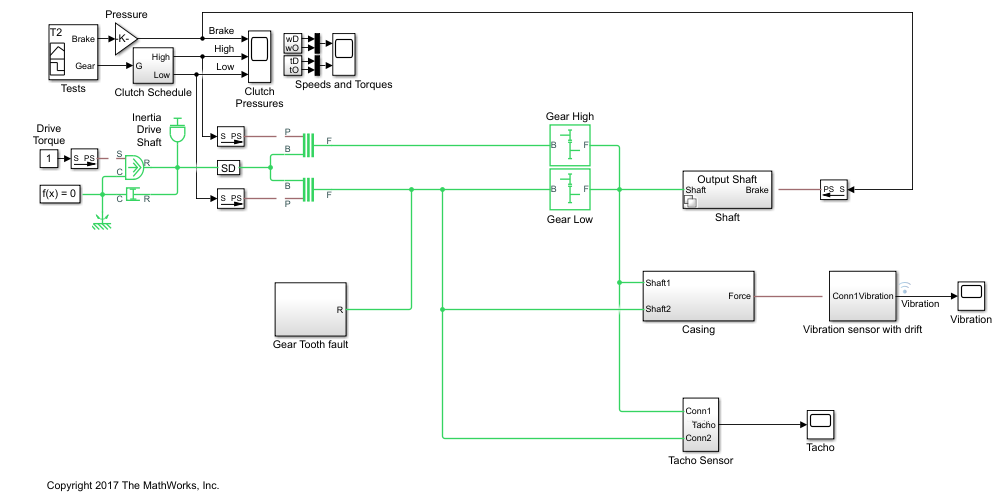

The transmission system includes a vibration sensor that is monitoring casing vibrations. The casing model translates the shaft angular displacement to a linear displacement on the casing. The casing is modelled as a mass spring damper system and the vibration (casing acceleration) is measured from the casing. 

open_system([mdl '/Casing'])


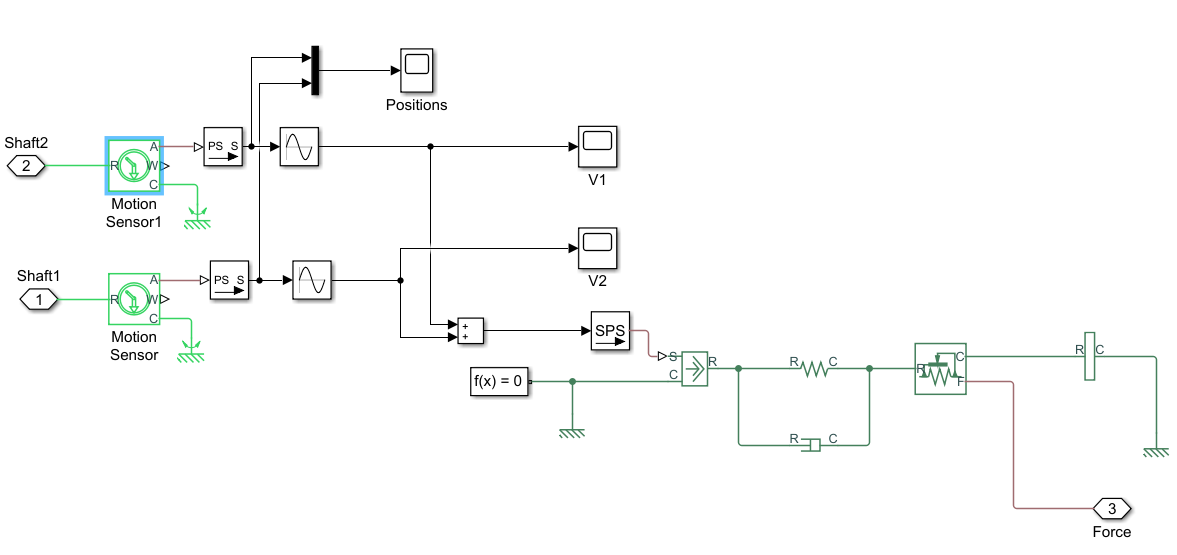

## Fault Modelling

The transmission system includes fault models for vibration sensor drift, gear tooth fault, and shaft wear. The sensor drift fault is easily modeled by introducing an offset in the sensor model. The offset is controlled by the model variable `SDrift`, note that `SDrift=0` implies no sensor fault. 

Pełzanie (dryft) (ang. drift) obejmuje zmiany sygnału wyj-

ściowego przetwornika, które mają miejsce nawet wtedy, gdy

nie występują żadne zmiany wielkości mierzonej lub warun-

ków środowiskowych. Jedyną zmienną podczas pomiaru

dryftu jest upływ czasu [127].

open_system([mdl '/Vibration sensor with drift'])

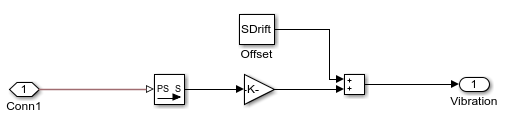

Zuycie walu

The shaft wear fault is modeled by a variant subsystem. In this case the subsystem variants change the shaft damping but the variant subsystem could be used to completely change the shaft model implementation. The selected variant is controlled by the model variable` ShaftWear`, note that` ShaftWear=0` implies no shaft fault.

open_system([mdl '/Shaft'])

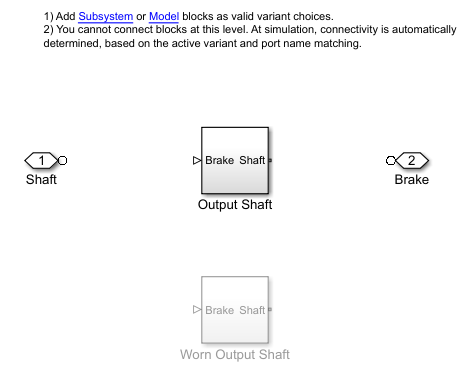

open_system([mdl,'/Shaft/Output Shaft'])

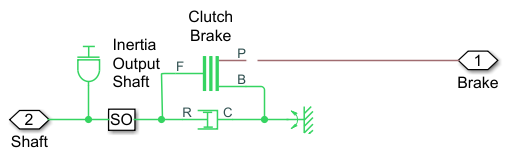

Uszkodzenie zeba przekadni

The gear tooth fault is modelled by injecting a disturbance torque at a fixed position in the rotation of the drive shaft. The shaft position is measured in radians and when the shaft position is within a small window around 0 a disturbance force is applied to the shaft. The  magnitude of the disturbance is controlled by the model variable `ToothFaultGain`, note that `ToothFaultGain=0` implies no gear tooth fault.

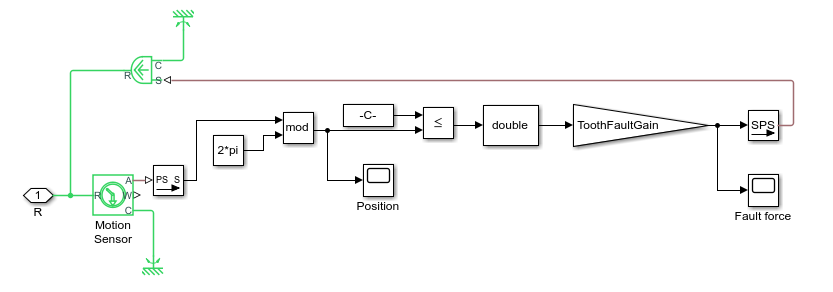

## Simulating Fault and Healthy Data

The transmission model is configured with variables that control the presence and severity of the three different fault types, sensor drift, gear tooth, and shaft wear.  By varying the model variables, `SDrift`, `ToothFaultGain`, and `ShaftWear`, you can create vibration data for the different fault types. Use an array of `Simulink.SimulationInput` objects to define a number of different simulation scenarios. For example, choose an array of values for each of the model variables and then use the `ndgrid` function to create a `Simulink.SimulationInput` for each combination of model variable values. 

toothFaultArray = -2:1/10:0; % Tooth fault gain values
sensorDriftArray = -1:0.1:1; % Sensor drift offset values
shaftWearArray = [0 -1];       % Variants available for drive shaft conditions

% Create an n-dimensional array with combinations of all values
[toothFaultValues,sensorDriftValues,shaftWearValues] = ...
    ndgrid(toothFaultArray,sensorDriftArray,shaftWearArray);

t = (0:0.1:30);
timeserie = timeseries(5*ones(size(t)),t)

  timeseries

  Common Properties:
            Name: 'unnamed'
            Time: [301x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [1x1x301 double]
        DataInfo: 


for ct = numel(toothFaultValues):-1:1
    % Create a Simulink.SimulationInput for each combination of values
    siminput = Simulink.SimulationInput(mdl);
    % Modify model parameters
    %siminput = setExternalInput(siminput, [t, timeserie]);
    %siminput = setVariable(siminput,'timeserie',ds);
    %siminput = setVariable(siminput,'timeserie',1);
    %siminput = setVariable(siminput,'ToothFaultGain',toothFaultValues(ct));
    siminput = setVariable(siminput,'ToothFaultGain',toothFaultValues(ct));
    siminput = setVariable(siminput,'SDrift',sensorDriftValues(ct));
    siminput = setVariable(siminput,'ShaftWear',shaftWearValues(ct));
    
    % Collect the simulation input in an array
    gridSimulationInput(ct) = siminput;
end

Similarly create combinations of random values for each model variable. Make sure to include the `0` value so that there are combinations where only subsets of the three fault types are represented.

rng('default'); % Reset random seed for reproducibility
toothFaultArray = [0 0 0 0 -rand(1,6)];    % Tooth fault gain values
sensorDriftArray = [0 0 0 0 randn(1,6)/8]; % Sensor drift offset values
shaftWearArray = [0 0 0 0 -1 -1 -1 -1];               % Variants available for drive shaft conditions

%Create an n-dimensional array with combinations of all values
[toothFaultValues,sensorDriftValues,shaftWearValues] = ...
    ndgrid(toothFaultArray,sensorDriftArray,shaftWearArray);

for ct=numel(toothFaultValues):-1:1
    % Create a Simulink.SimulationInput for each combination of values
    siminput = Simulink.SimulationInput(mdl);
    % Modify model parameters
    %siminput = setExternalInput(siminput, [t, timeserie]);
    %siminput = setVariable(siminput,'timeserie',ds);
    %siminput = setVariable(siminput,'timeserie',1);
    siminput = setVariable(siminput,'ToothFaultGain',toothFaultValues(ct));
    siminput = setVariable(siminput,'SDrift',sensorDriftValues(ct));
    siminput = setVariable(siminput,'ShaftWear',shaftWearValues(ct));
    % Collect the simulation input in an array
    randomSimulationInput(ct) = siminput;
end

With the array of `Simulink.SimulationInput` objects defined use the `generateSimulationEnsemble` function to run the simulations. The `generateSimulationEnsemble` function configures the model to save logged data to file, use the timetable format for signal logging and store the `Simulink.SimulationInput` objects in the saved file. The `generateSimulationEnsemble` function returns a status flag indicating whether the simulation completed successfully. 

The code above created 110 simulation inputs from the gridded variable values and `98 `simulation inputs from the random variable values giving 208 total simulations. Running these 208 simulations in parallel can take as much as two hours or more on a standard desktop and generates around 10GB of data. An option to only run the first 10 simulations is provided for convenience. 

% Run the simulations and create an ensemble to manage the simulation results
if ~exist(fullfile(pwd,dir_to_write),'dir')
    mkdir(fullfile(pwd,dir_to_write)) % Create directory to store results
end
runAll = true;
if runAll
   [ok,e] = generateSimulationEnsemble([gridSimulationInput, randomSimulationInput], ...
        fullfile(pwd,dir_to_write),'UseParallel', true);
else
    [ok,e] = generateSimulationEnsemble(gridSimulationInput(1:10), fullfile(pwd,'Data_22_07')); %#ok<*UNRCH>
end

[16-Aug-2022 22:18:18] Checking for availability of parallel pool...
Starting parallel pool (parpool) using the 'local' profile ...
Preserving jobs with IDs: 13 because they contain crash dump files.
You can use 'delete(myCluster.Jobs)' to remove all jobs created with profile local. To create 'myCluster' use 'myCluster = parcluster('local')'.
Connected to the parallel pool (number of workers: 4).
[16-Aug-2022 22:20:35] Starting Simulink on parallel workers...
[16-Aug-2022 22:22:12] Configuring simulation cache folder on parallel workers...
[16-Aug-2022 22:22:13] Loading model on parallel workers...
[16-Aug-2022 22:24:21] Transferring base workspace variables used in the model to parallel workers...
[16-Aug-2022 22:24:47] Running simulations...


[16-Aug-2022 22:51:56] Completed 1 of 208 simulation runs
[16-Aug-2022 22:51:59] Completed 2 of 208 simulation runs
[16-Aug-2022 22:52:02] Completed 3 of 208 simulation runs
[16-Aug-2022 22:52:04] Completed 4 of 208 simulation runs
[16-Aug-2022 23:16:38] Completed 5 of 208 simulation runs
[16-Aug-2022 23:16:41] Completed 6 of 208 simulation runs
[16-Aug-2022 23:16:51] Completed 7 of 208 simulation runs
[16-Aug-2022 23:16:53] Completed 8 of 208 simulation runs
[16-Aug-2022 23:41:12] Completed 9 of 208 simulation runs
[16-Aug-2022 23:41:35] Completed 10 of 208 simulation runs
[16-Aug-2022 23:41:37] Completed 11 of 208 simulation runs
[16-Aug-2022 23:41:39] Completed 12 of 208 simulation runs
[17-Aug-2022 00:05:47] Completed 13 of 208 simulation runs
[17-Aug-2022 00:05:50] Completed 14 of 208 simulation runs
[17-Aug-2022 00:06:04] Completed 15 of 208 simulation runs
[17-Aug-2022 00:06:25] Completed 16 of 208 simulation runs
[17-Aug-2022 00:30:13] Completed 17 of 208 simulation runs
[17-Au

The `generateSimulationEnsemble` ran and logged the simulation results. Create a simulation ensemble to process and analyze the simulation results using the `simulationEnsembleDatastore` command.

ens = simulationEnsembleDatastore(fullfile(pwd,dir_to_write));

## Processing the Simulation Results

The `simulationEnsembleDatastore` command created an ensemble object that points to the simulation results. Use the ensemble object to prepare and analyze the data in each member of the ensemble. The ensemble object lists the data variables in the ensemble and by default all the variables are selected for reading.

ens

ens =   simulationEnsembleDatastore with properties:

           DataVariables: [10×1 string]
    IndependentVariables: [0×0 string]
      ConditionVariables: [0×0 string]
       SelectedVariables: [10×1 string]
                ReadSize: 1
              NumMembers: 208
          LastMemberRead: [0×0 string]
                   Files: [208×1 string]


ens.SelectedVariables

ans = 10×1 string array
    "AngularVelocity"
    "Brake"
    "Gear"
    "SimulationInput"
    "SimulationMetadata"
    "Tacho"
    "Torque"
    "Vibration"
    "xFinal"
    "xout"


For analysis only read the `Vibration` and `Tacho` signals and the `Simulink.SimulationInput`. The `Simulink.SimulationInput `has the model variable values used for simulation and is used to create fault labels for the ensemble members. Use the ensemble `read` command to get the ensemble member data.

ens.SelectedVariables = ["Vibration" "Tacho" "SimulationInput" "AngularVelocity" "Gear" "Torque" "Brake"];
data = read(ens)

data = 1×7 table
         Vibration                Tacho                  SimulationInput              AngularVelocity             Gear                  Torque                  Brake       
    ___________________    ___________________    ______________________________    ___________________    ___________________    ___________________    ___________________

    {50001×1 timetable}    {50001×1 timetable}    {1×1 Simulink.SimulationInput}    {50001×1 timetable}    {50001×1 timetable}    {50001×1 timetable}    {50001×1 timetable}


%ens.DataVariables = [ens.DataVariables; "TachoPulses"];

The ensemble `ConditionVariables` property can be used to identify the variables in the ensemble that contain condition or fault label data. Set the property to contain the newly created fault labels.

ens.ConditionVariables = ["SensorDrift","ShaftWear","ToothFault","FaultCode"];

The code above was used to process one member of the ensemble. To process all the ensemble members the code above was converted to the function `prepareData `and using the ensemble `hasdata` command a loop is used to apply `prepareData` to all the ensemble members. The ensemble members can be processed in parallel by partitioning the ensemble and processing the ensemble partitions in parallel.

reset(ens)
runLocal = false;
if runLocal
    % Process each member in the ensemble
    while hasdata(ens)
        data = read(ens);
        addData = prepareData_2(data);
        writeToLastMemberRead(ens,addData)
    end
else
    % Split the ensemble into partitions and process each partition in parallel
    n = numpartitions(ens,gcp);
    parfor ct = 1:n
        subens = partition(ens,n,ct);
        while hasdata(subens)
            data = read(subens);
            addData = prepareData_2(data);
            writeToLastMemberRead(subens,addData)
        end
    end    
end

Plot the vibration signal of every 10th member of the ensemble using the `hasdata` and `read` commands to extract the vibration signal.